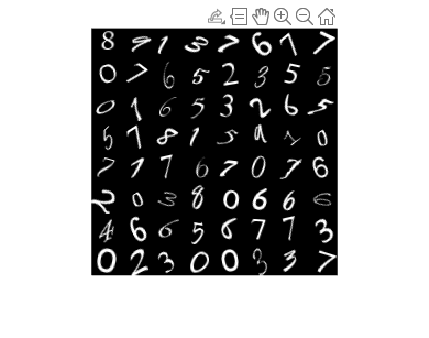

[XTrain,T1Train,T2Train] = digitTrain4DArrayData;
numObservations = numel(T1Train);
idx = randperm(numObservations,64);
I = imtile(XTrain(:,:,:,idx));
figure
imshow(I)

XTrain(:,:,:,1)

ans =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 

if iscategorical(T1Train)

ans =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


    T1Train_numeric = double(string(T1Train));
else
    T1Train_numeric = T1Train; % If it's already double, just use it
end

% Assuming XTrain, T1Train are loaded as in your code

% 1. Pick two numbers (e.g., '3' and '8')
targetDigit1 = 0;
targetDigit2 = 6;

% Find indices for these digits
idxDigit1 = find(T1Train_numeric == targetDigit1);
idxDigit2 = find(T1Train_numeric == targetDigit2);

% Combine indices and get corresponding data and labels
selectedIndices = [idxDigit1; idxDigit2];
X_subset_images = XTrain(:,:,:,selectedIndices);
T_subset_labels = T1Train_numeric(selectedIndices);
T_subset_labels(T_subset_labels==targetDigit1) = 1;
T_subset_labels(T_subset_labels==targetDigit2) = 2;


% 2. Feature Extraction (flatten images for simplicity)
numImagesSubset = numel(T_subset_labels);

Error using load
Unable to find file or directory "SampleImagePatches". It is used in these examples: 
  Create Reconstruction ICA Object
  Create Sparse Filter
  Restart sparsefilt
  Transform Data to Learned Features

% Assuming images are HxW, flatten to 1D feature vectors
[H, W, C, ~] = size(X_subset_images);
X_features = reshape(X_subset_images, H*W*C, numImagesSubset)'; % Each row is a feature vector
 

obj = sparsefilt(X_features,300 )

obj =   SparseFiltering
            ModelParameters: [1×1 struct]
              NumPredictors: 784
         NumLearnedFeatures: 300
                         Mu: []
                      Sigma: []
                    FitInfo: [1×1 struct]
           TransformWeights: [784×300 double]
    InitialTransformWeights: []


  Properties, Methods


clusterAssignments = kmeans(X_features, 2);
 get_bicluster_accuracy(clusterAssignments, T_subset_labels)

ans = 0.5460

sol_spec = spectralcluster(X_features, 2);
 get_bicluster_accuracy(sol_spec, T_subset_labels)

ans = 0.5170

 sol_ifpca = ifpca(X_features', 2);

Error using eigs>KSnonherm (line 1589)
Input matrix is badly conditioned. It might contain Inf or NaN.

Error in eigs>KrylovSchur (line 1336)
    [V, d, isNotConverged, stopAlgorithm, VV] = KSnonherm(applyOP, applyM, n, k, ...

Error in eigs (

  get_bicluster_accuracy(sol_ifpca, T_subset_labels)

  ours = sdp_kmeans_iter_knowncov_NMF(X_features', 2);
 sol_our = ours.fit_predict(10, clusterAssignments)


1 th iteration

148 entries survived 


2 th iteration

116 entries survived 


3 th iteration

135 entries survived 


4 th iteration

134 entries survived 


5 th iteration

133 entries survived 


6 th iteration

133 entries survived 


7 th iteration

133 entries survived 


8 th iteration

134 entries survived 


9 th iteration

133 entries survived 


10 th iteration

133 entries survived 



sol_our =      2     2     2     2     2     2     1     1     2     2     2     1     2     2     1     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     1     2     2     2     1     2     2     2     1     2     2     2


 get_bicluster_accuracy(sol_our, T_subset_labels)

ans = 0.5940